This demo shows how to read 1D results from a parametric sweep and how they can be re-arranged in a more convenient for interpreting way.

**!!! IMPORTANT !!!**

**Before running this Live script, manually run the parametric sweep in the CST project "CST\Two_dipoles_ParamSweep_FD.cst" from the CST GUI (*****Home tab - Par.Sweep - Start*****).**

clc
clear

Connect to the project. Here we used frequency domain solver.

CSTProject = 'CST\Two_dipoles_ParamSweep_FD.cst';
CST = TCSTInterface();
CST.OpenProject(CSTProject);

Connected to project "E:\01_Toolboxes\CSTMWS-Matlab-Interface\Demos\CST\Two_dipoles_ParamSweep_FD.cst"


Here we suppress the CST interface output to the Matlab command window since it is not important for this demo:

CST.SilentMode = true;

# Getting parameric sweep results

## Syntax

If some parametric sweep has been perfomed, the results for each Run ID can be read using the following method:

The function returns an object `Res`, which contains all requested results for all requested Run IDs.

All arguments, except 1st one, are optional. The `RunIDFilter` is equal to `NaN` by default, meaning that RunID 0 (current run) is excluded from the reading.

`RunIDFilter` is the Run ID filter, as explained in the demo "a010_Basics".

The extra parameter name-value pairs can be as following:

- `'VarNames', {'Name1','Name2', ...}` -  The default result names in `Res` can be changed. See example below.

- `'CacheFile', MatFileName` - One can specify a mat-file, in which the read results will be saved. If the file exists, the results will be loaded from it insted of getting them from CST. If some results are missing in the cache file, they will be obtained from CST and saved to the cache file.

- `'SplitParameters', true` or `false` - The results will be reshaped in a such way that each dimension of them corresponds to a single parameter in CST. See an example below. 

- `'QueryX', [x1 x2 ...]` - We can request the data at the specified points, which are expressed in units like in the corresponding plot in CST. For example, if the x-coordinate for S-parameters is the frequency in GHz, `QueryX` is the frequencies in GHz then, when reading the S-parameters.

Below are some usage examples.

## Getting several results

Specify Tree Items which we would like to read. It can be any valid 1D result (like first 2 elements in `ResultsToRead` below). There are also two special cases: full S- or Z-matrix (as 3rd element in `ResultsToRead` below):

ResultsToRead = {
    '1D Results\S-Parameters\S1,1', ...
    '1D Results\Efficiencies\Rad. Efficiency [1]', ...
    'S'
};

Perform actual reading and display the retrieved data:

Res = CST.ReadParametricResults(ResultsToRead);
Res

TResultsStorage object Res containing the following variables:
===========================================================================================================================================
Name                | Value                | Arguments              | Units | Description                                                  
===========================================================================================================================================
Zref                | 65                   |                        |       | 'Reference impedance for the S-parameters'                   
m                   | <1×2 double>         |                        |       | 'Port index'                                      

The results are stored in the object `Res`, and displayed in the table above. They can be accessed using usual dot-notation, e.g. `Res.RadiationEfficiency`.

Each requested result is stored as a function of several arguments. In the example above `Res.RadiationEfficiency` is a function of frequecy (`Res.Frequecy_GHz`) and Run ID (`Res.RunID`), which can be seen from the table. Values of each argument are also stored in `Res`.

## Giving custom variable names for the results 

Argument names are obtained from the X-label of the corresponding CST plot, and result names - from the CST plot title by default. To give them more meaningfull result names, one can customize them by using the `'VarNames',{'Name1','Name2',...}` argument pair:

VarNames = {'S11', 'RadEff', 'SMatrix'};
Res = CST.ReadParametricResults(ResultsToRead, nan, 'VarNames',VarNames)

TResultsStorage object Res containing the following variables:
=======================================================================================================================================
Name            | Value                | Arguments              | Units | Description                                                  
=======================================================================================================================================
Zref            | 65                   |                        |       | 'Reference impedance for the S-parameters'                   
m               | <1×2 double>         |                        |       | 'Port index'                                                 
n       

Here the 2nd argument (`RunIDFilter`) is NaN in order to exclude results for the current run (Run ID 0).

Let's plot S11 at 1 GHz as function of RunID:

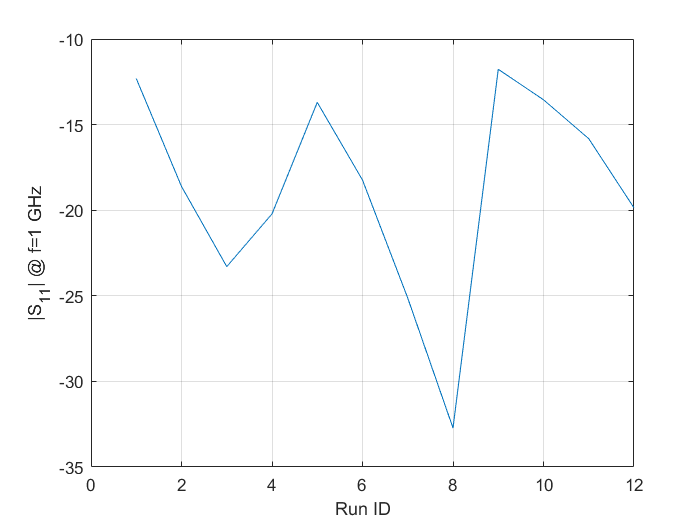

Freq = 1; % [GHz], i.e. units of the CST plot
d = abs(Res.Frequency_GHz_1 - Freq);    iFr = find(d==min(d),1);  % find closest frequency index
figure;
S11dB = 20*log10(abs(Res.S11));
plot(Res.RunID, S11dB(iFr,:));
grid on; xlabel('Run ID');  ylabel(sprintf('|S_{11}| @ f=%g GHz',Res.Frequency_GHz_1(iFr)));

## Splitting parameters

The plot above plot is difficult to interpret, because each Run ID corresponds to a combination of several parameter values. E.g. RunID 1 is for the CST parameters `DipLenLam`=0.44 and `DipSeparation`=50, and RunID 8 is for the CST parameters `DipLenLam`=0.45 and `DipSeparation`=125 (to see that, just look in the *Result Navigator* of the CST project, or use `GetParameterCombination` method of the interface as shown in demo "a010_Basics").

Sometimes we want to see an influence of each individual parameter on the result. It is possible to reshape the "Run ID" dimension of the stored results in several dimensions in a such way that each new dimension corresponds to a single parameter. To do so, we specify an additional input argument pair `'SplitParameters',true`:

ResultsToRead = '1D Results\S-Parameters\S1,1';
VarNames = 'S11';
Res = CST.ReadParametricResults(ResultsToRead, nan, 'VarNames',VarNames, 'SplitParameters',true)

TResultsStorage object Res containing the following variables:
====================================================================================================================================
Name          | Value             | Arguments                               | Units | Description                                   
====================================================================================================================================
DipLenLam     | <1×3 double>      |                                         |       |                                               
DipSeparation | <1×4 double>      |                                         |       |                                               
Frequency_GHz | <1001×1

So, now `Res.S11`'s second dimension (RunID) has been reshaped such that instead of having S11 as function of the frequency and RunID, we have S11 as function of the frequency and the nodel parameters `DipLenLam` and `DipSeparation`.

Now we can plot S11 as function of two swept parameters (`DipLenLam` and `DipSeparation`) at 1 GHz:

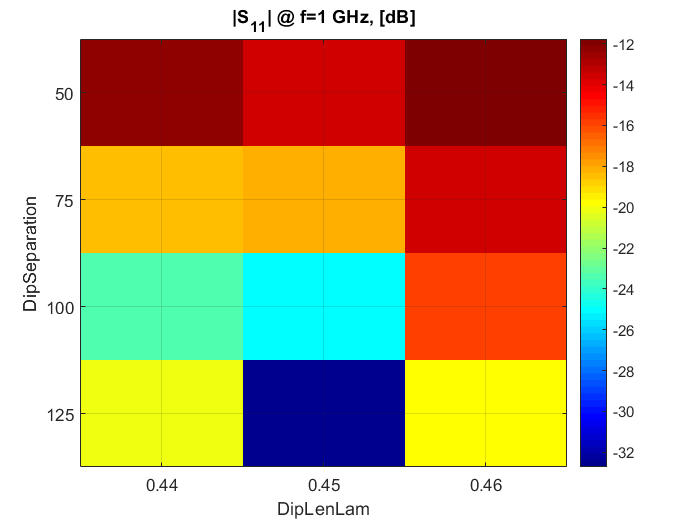

Freq = 1; % [GHz], i.e. units of the CST plot
d = abs(Res.Frequency_GHz - Freq);    iFr = find(d==min(d),1);  % find closest frequency index
figure;
S11dB = 20*log10(abs( Res.S11(iFr,:,:) ));
imagesc(Res.DipLenLam, Res.DipSeparation, squeeze(S11dB).');
grid on; xlabel('DipLenLam');  ylabel('DipSeparation');  title(sprintf('|S_{11}| @ f=%g GHz, [dB]',Res.Frequency_GHz(iFr)));
set(gca, 'XTick',Res.DipLenLam, 'YTick',Res.DipSeparation); colormap jet;  colorbar;

*(Here we use Matlab's *`imagesc`* function for visualization of 2D data, however it is only valid when arguments have constant steps, like in this demo)*

It may happen that values of the parameters do not form a grid. In this case data for non-excisting paramter combinations will be *NaN*. The figure below explains example of a such case.

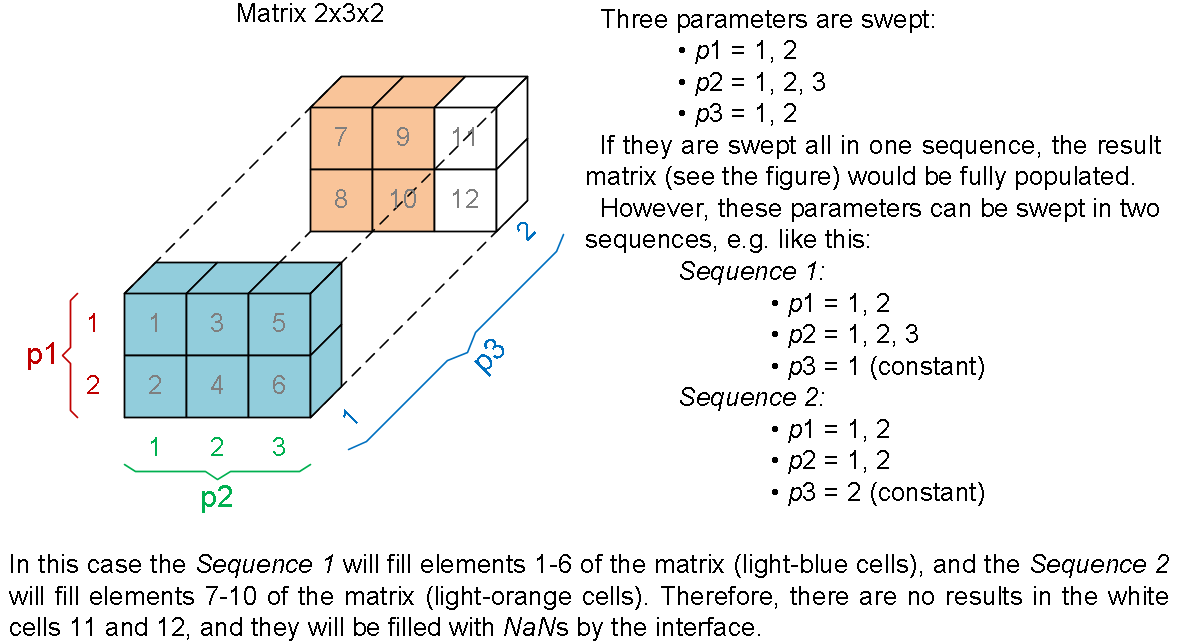

## Getting results when each Run ID has different number of points

For some simulation setups it may happen that some results have different x-coordinates for the data points for each Run ID. Since the retrieved data is organized in matrices, these situations are not allowed. For example, the following code will give an error for this CST project:

ResultToRead = '1D Results\Power\Excitation [1]\Power Accepted';
try % here we use try-catch block to print the error message without stopping execution of this demo
    Res = CST.ReadParametricResults(ResultToRead)
catch ME
    fprintf(2,ME.message);
end

X for Run ID "3D:RunID:2" is not the same as for the previous ones. This is not supported.
You may consider specifying QueryX as an additional input argument together with setting NearesOrInterpolated to 'Interpolated'

And indeed, if we look the accepted power in CST, the points for each Run ID are different. We can also see it using the following code:

for runid=0:4,
    Freq = CST.Get1DResultFromTreeItem(ResultToRead,runid);    
    srtFreq = sprintf('%.4f  ', Freq);
    fprintf('Frequencies for Run ID %i:   %s\n', runid,srtFreq);
end

Frequencies for Run ID 0:   0.7500  0.8000  0.8725  0.9165  0.9305  1.0000  1.0705  1.2000  1.2500  
Frequencies for Run ID 1:   0.7500  0.8000  0.8850  0.9435  1.0000  1.0525  1.2000  1.2500  
Frequencies for Run ID 2:   0.7500  0.8000  0.8810  0.9415  1.0000  1.0490  1.2000  1.2500  
Frequencies for Run ID 3:   0.7500  0.8000  0.8800  0.9405  1.0000  1.0610  1.2000  1.2500  
Frequencies for Run ID 4:   0.7500  0.8000  0.8805  0.9415  1.0000  1.0760  1.2000  1.2500  


To overcome this limitation we can set `NearestOrInterpolated` property of the interface to `'interpolated'`, and specify X-coordinates (frequencies in this case) for which we want to get the result(s):

CST.NearestOrInterpolated = 'interpolated';
QueryFreqs = 0.75:0.01:1.25; % 51 frequency points
Res = CST.ReadParametricResults(ResultToRead, nan, 'QueryX',QueryFreqs)

TResultsStorage object Res containing the following variables:
================================================================================================================================
Name          | Value          | Arguments            | Units | Description                                                     
================================================================================================================================
Frequency_GHz | <51×1 double>  |                      |       |                                                                 
RunID         | <12×1 double>  |                      | '-'   | 'Run ID in the CST Result Navigator'                            
PowerInW      | <51×12 double> | Frequency_

Now everything works without errors and is organized in convenient matrix form.